# 2주차 — 모델링: 물리 법칙에서 전달함수까지

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

1주차에서 $G(s) = \frac{1}{ms^2+bs+k}$ 를 하늘에서 떨어진 것처럼 유도 없이 받아 썼습니다. 이번 주에는 이 물건이 **어디서 오는지**, 그리고 이것만 보고 무엇을 알 수 있는지를 다룹니다.

오늘의 질문

- 물리 법칙에서 전달함수까지 가는 길은 어떤 단계인가

- 전달함수를 보면 시스템에 대해 무엇을 알 수 있는가

- 극점과 영점은 정확히 무엇이고 왜 그렇게 중요한가

- 전달함수가 표현하지 못하는 것이 있는가

함께 쓰는 파일

- `W02_01_tf_basics.m` — 전달함수 만들기, 극점과 응답의 대응

- `W02_02_msd_derivation.m` — 물리에서 전달함수 유도, 극점의 이동

- `W02_03_run_simulink.m` — Simulink 세 가지 구현 비교

- `W02_MSD_ThreeWays.slx` — 블록선도 모델

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 강의노트의 절 번호와 스크립트의 절 번호가 서로 맞도록 만들어 두었습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체를 돌리려면 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 그림은 대부분 `make_figures.m` 이 미리 만들어 문서에 박아 둔 것입니다. 그림을 고치고 싶으면 그 파일의 해당 함수를 고친 뒤 `make_figures()` 를 다시 돌립니다.

## 0. 오늘 한 장 요약

오늘 하는 일은 이 화살표를 따라가는 것입니다.


$$\text{물리 법칙} \rightarrow \text{미분방정식} \rightarrow \text{라플라스 변환} \rightarrow \text{전달함수}$$


**전달함수**란 "이렇게 넣으면 저렇게 나온다" 를 식 하나로 적어 둔 것입니다. 아래 그림에서 상자 $G(s)$ 안에 들어가는 것이 바로 그것입니다.

오늘의 계단

- **1~5절** 네 단계를 질량-스프링-댐퍼에 적용

- **6~8절** 극점이 무엇이고 왜 응답을 결정하는가

- **9~11절** 댐퍼를 바꾸면 극점이 어디로 가는가, 영점은 무슨 일을 하는가

- **13절** Simulink 로 같은 시스템을 세 가지 방법으로 만들어 겹쳐 보기

오늘 딱 하나만 기억한다면 이것입니다.

- **극점의 위치가 응답의 모양을 정한다**

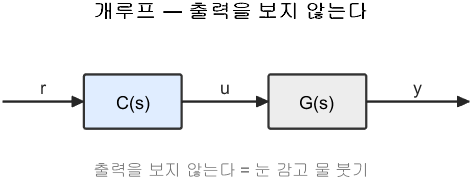

개루프 — 출력을 보지 않는다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('open', ...)` 로 부릅니다

그림 해석

1주차에서는 이 그림과 폐루프를 비교했습니다. 오늘은 **상자 하나를 어떻게 채우는가**만 봅니다. 되먹임은 다음 주부터입니다.

## 0-1. 가장 작은 예부터

이해를 돕기 위해 제일 쉬운 것부터 봅니다.


$$G(s) = \frac{1}{s+1}$$


이 전달함수의 극점은 $s = -1$ 하나뿐입니다. 극점이 하나면 응답도 아주 단순합니다. 단조롭게 올라가 멈춥니다.

G_tiny = 1/(s+1);
fprintf('가장 작은 예 : G(s) = 1/(s+1)\n');

가장 작은 예 : G(s) = 1/(s+1)


fprintf('  극점    : %.1f\n', pole(G_tiny));

  극점    : -1.0


fprintf('  DC 이득 : %.1f  (천천히 넣으면 그대로 나온다)\n', dcgain(G_tiny));

  DC 이득 : 1.0  (천천히 넣으면 그대로 나온다)


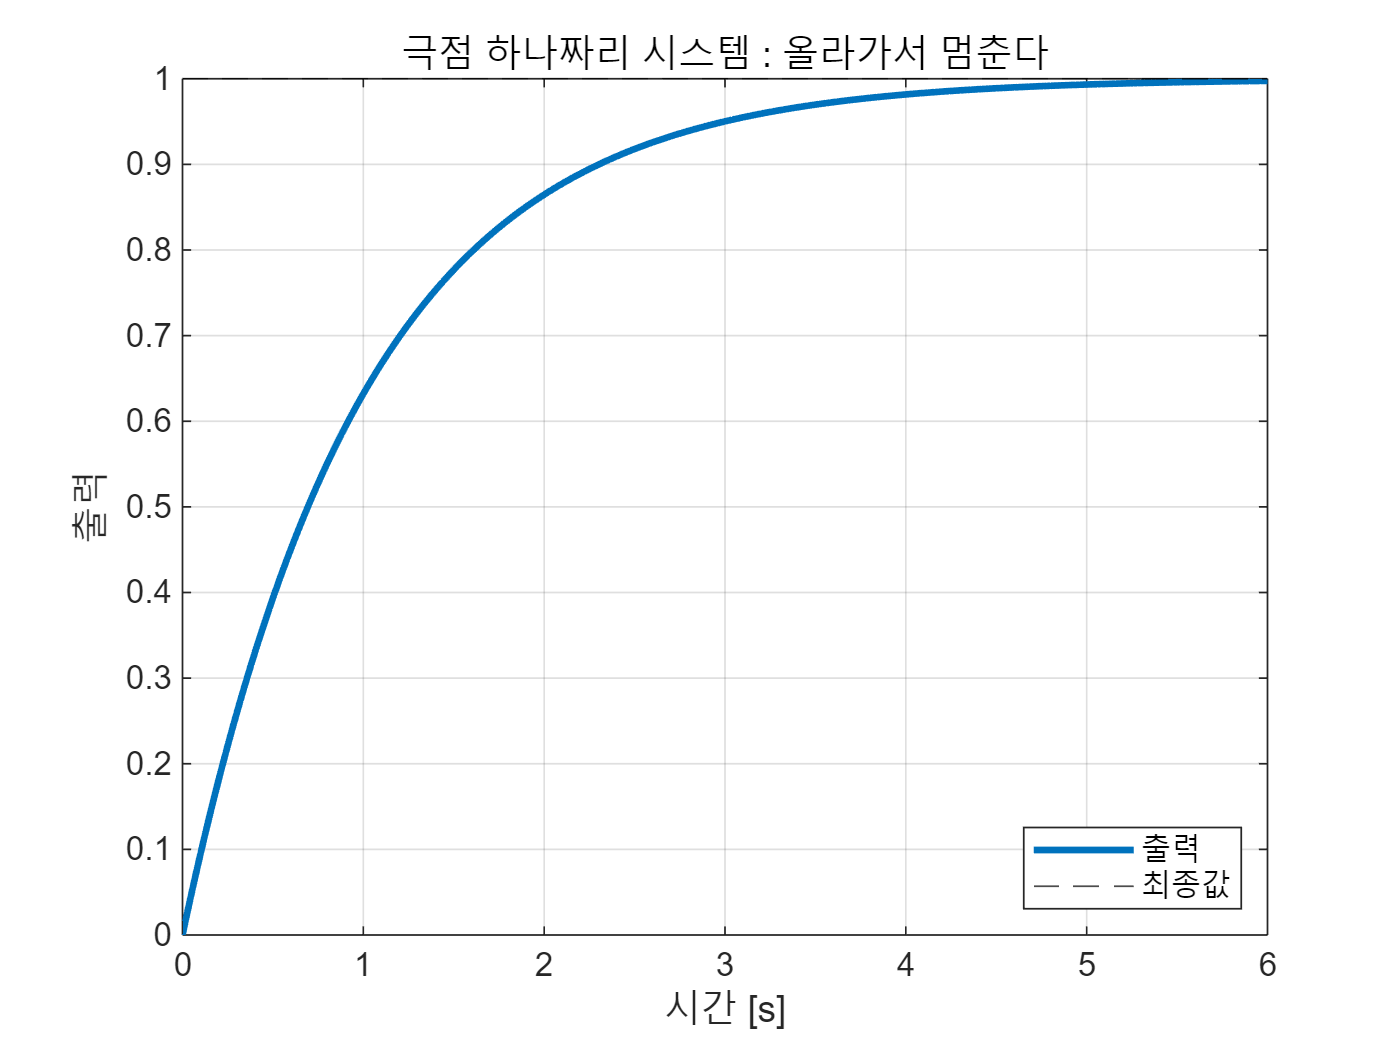

t0 = (0:0.02:6)';
plot(t0, step(G_tiny, t0), 'LineWidth', 2); hold on;
yline(1, 'k--'); grid on;
xlabel('시간 [s]'); ylabel('출력');
legend('출력', '최종값', 'Location', 'southeast');
title('극점 하나짜리 시스템 : 올라가서 멈춘다');

## 0-2. 극점을 옮겨 보면

극점 위치만 바꿔도 응답이 이렇게 달라집니다. 오늘 배울 것을 한 그림으로 미리 보는 셈입니다.

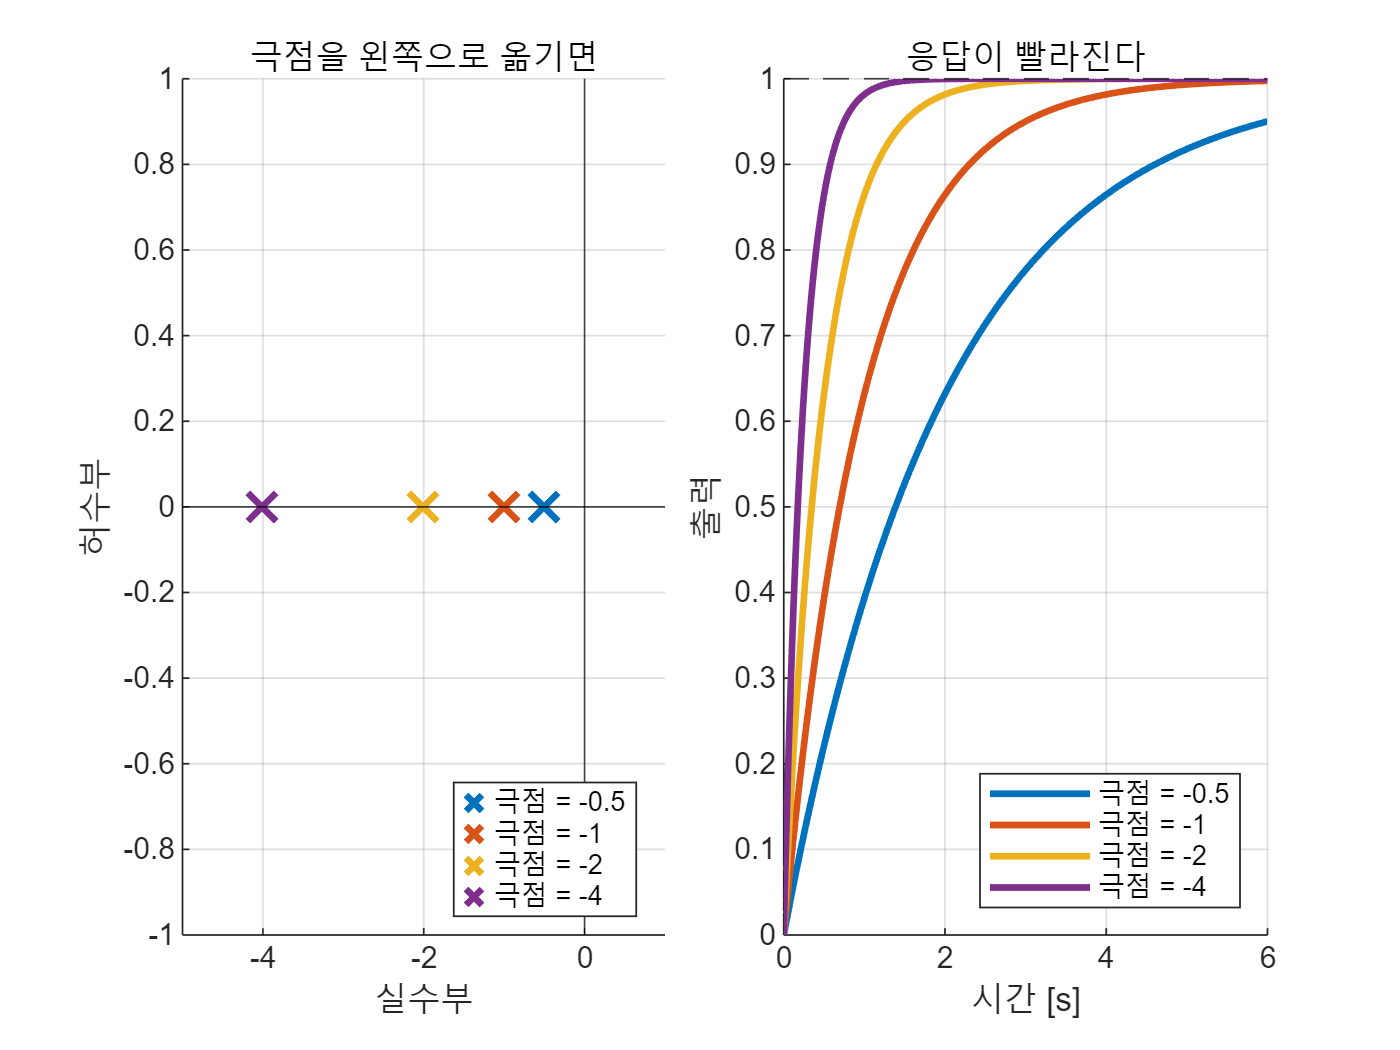

figure;
tiledlayout(1,2,'TileSpacing','compact');
nexttile
hold on; grid on;
for p = [0.5 1 2 4]
    plot(-p, 0, 'x', 'MarkerSize', 12, 'LineWidth', 2, ...
         'DisplayName', sprintf('극점 = %g', -p));
end
xline(0,'k-','HandleVisibility','off'); yline(0,'k-','HandleVisibility','off');
xlim([-5 1]); ylim([-1 1]);
xlabel('실수부'); ylabel('허수부');
title('극점을 왼쪽으로 옮기면');
legend('Location','best');
nexttile
hold on; grid on;
for p = [0.5 1 2 4]
    plot(t0, step(p/(s+p), t0), 'LineWidth', 2, ...
         'DisplayName', sprintf('극점 = %g', -p));
end
yline(1,'k--','HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력');
title('응답이 빨라진다');
legend('Location','southeast');

## 1. 왜 모델이 필요한가

제어기를 설계하려면 "이렇게 넣으면 저렇게 반응한다"는 것을 알아야 합니다. 그 지식을 수학으로 적어 놓은 것이 모델입니다.

모델 없이 시행착오로 맞출 수도 있고 현장에서 실제로 그렇게 하기도 합니다. 하지만 이럴 때는 불가능합니다.

- 위험하다 — 항공기

- 비싸다 — 선박

- 느리다 — 화학공정

그리고 모델이 있으면 시행착오로는 절대 알 수 없는 것을 알 수 있습니다. 예를 들어 **이득을 얼마까지 키우면 불안정해지는가** 같은 질문에 미리 답할 수 있습니다.

## 2. 모델링의 네 단계

어떤 시스템이든 절차는 똑같습니다.

- 물리 법칙을 적는다 — 뉴턴 법칙, 키르히호프 법칙 등

- 미분방정식으로 정리한다

- 라플라스 변환한다 — 초기조건은 $0$ 으로 둔다

- 출력을 입력으로 나눠 전달함수를 얻는다

1~2 는 동역학이고 3~4 가 제어공학입니다. 하지만 1~2 가 틀리면 그 뒤가 전부 무의미해집니다. **모델링이 제어 설계보다 어려운 경우가 많습니다.**

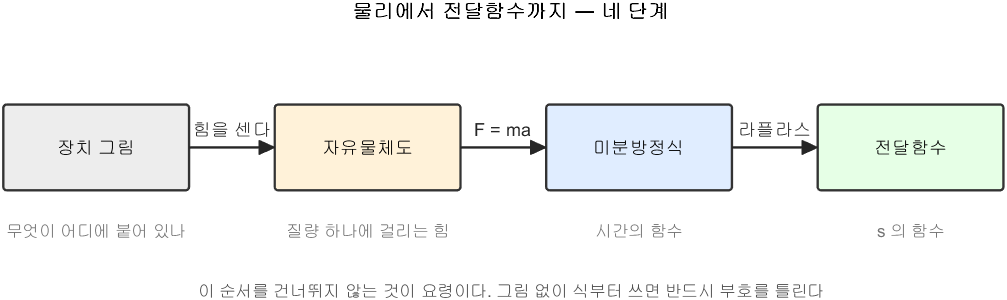

물리에서 전달함수까지 — 네 단계

**그림 파일** `modeling_steps.png` — `common/dg_modeling_steps.m` 의 `dg_modeling_steps` · 다시 만들려면 `make_figures('modeling_steps')`

**만드는 곳** — `make_figures.m` 의 `dg_modeling_steps` **직접 밟아 보려면** — `W02_02_msd_derivation.m` 을 처음부터 끝까지 실행

그림 해석

이 순서를 **건너뛰지 않는 것**이 요령입니다. 그림 없이 식부터 쓰면 힘의 방향을 반드시 한 번은 틀립니다. 아래 3~5 절에서 이 네 칸을 하나씩 밟습니다.

## 3. 1단계 — 장치를 그림으로 그린다

식부터 쓰지 마십시오. **먼저 그림을 그립니다.**

질량 $m$ 인 물체가 스프링 $k$ 와 댐퍼 $b$ 로 벽에 매달려 있고, 힘 $F(t)$ 를 가합니다. 오른쪽으로 움직인 거리를 $x(t)$ 라 하고, **오른쪽을 **$+$ 로 잡습니다.

부호를 어디로 잡을지 여기서 정해 두어야 뒤가 안 꼬입니다.

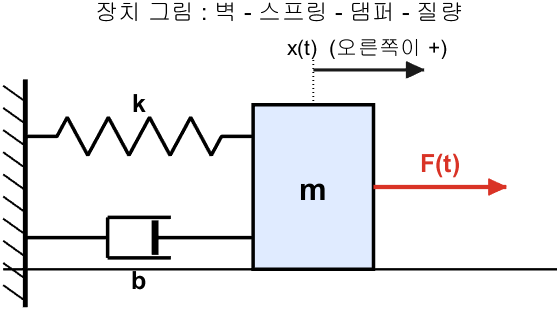

질량-스프링-댐퍼 장치 그림

**그림 파일** `msd_only.png` — `common/dg_msd.m` 의 `dg_msd` · 다시 만들려면 `make_figures('msd_only')`

**만드는 곳** — `common/dg_msd.m` 을 `dg_msd('system')` 으로 부릅니다 **직접 확인해 보려면** — `W02_02_msd_derivation.m` 의 **1절**

그림 해석

부품이 셋뿐인데 왜 2차가 되는가 — **에너지를 저장하는 곳이 둘**이기 때문입니다. 스프링(위치에너지)과 질량(운동에너지)입니다. 댐퍼는 저장하지 않고 버립니다.

## 3-1. 2단계 — 자유물체도를 그린다

자유물체도란 **물체 하나만 떼어 내서 그 물체에 걸리는 힘만** 그린 그림입니다. 여기서 부호를 틀리면 그 뒤가 전부 틀립니다.

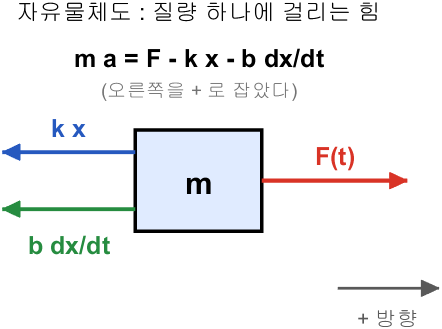

자유물체도 : 질량 하나에 걸리는 힘

**그림 파일** `msd_freebody.png` — `common/dg_msd.m` 의 `dg_msd` · 다시 만들려면 `make_figures('msd_freebody')`

**만드는 곳** — `common/dg_msd.m` 을 `dg_msd('freebody')` 로 부릅니다 **직접 확인해 보려면** — `W02_02_msd_derivation.m` 의 **1절**

그림 해석 — **화살표 방향을 그대로 부호로 옮기면 식이 됩니다**

**자유물체도를 먼저 그리는 이유**가 여기 있습니다. 그림 없이 식부터 쓰면 부호를 반드시 한 번은 틀립니다.

## 3-2. 힘을 하나씩 세어 본다

물체에 걸리는 힘은 셋입니다.

- **가한 힘** $+F(t)$ — 우리가 오른쪽으로 미는 힘

- **스프링 복원력** $-k\,x$ — 늘어난 만큼 되돌리려 한다. 그래서 부호가 $-$

- **댐퍼 저항력** $-b\,\dot{x}$ — 빠를수록 세게 방해한다. 그래서 부호가 $-$

스프링은 **위치**에, 댐퍼는 **속도**에 비례한다는 점이 중요합니다.

- 물체가 멈춰 있으면 댐퍼는 아무 일도 안 한다 ($\dot{x} = 0$)

- 물체가 제자리에 있으면 스프링은 아무 일도 안 한다 ($x = 0$)

이제 뉴턴의 제2법칙을 씁니다. "힘의 합 = 질량 $\times$ 가속도" 입니다.


$$F - k\,x - b\,\dot{x} \;=\; m\,\ddot{x} \qquad (\text{왼쪽이 힘의 합})$$


항을 옮겨 정리하면 이렇게 됩니다.


$$m\,\ddot{x} + b\,\dot{x} + k\,x = F$$


**여기서 잠깐 멈춥시다.**

- 이 식은 $x$ 에 대한 **2계** 미분방정식이다 (가장 높은 미분이 $\ddot{x}$)

- 뉴턴 법칙에 가속도가 들어 있으니 당연한 결과다

- 그리고 이 "2계" 라는 사실이 곧 **극점이 두 개** 라는 뜻이 된다

m = 1.0; b = 0.2; k = 1.0;
fprintf('=== 세운 미분방정식 ===\n');

=== 세운 미분방정식 ===


fprintf('  %.1f x'''' + %.1f x'' + %.1f x = F\n', m, b, k);

  1.0 x'' + 0.2 x' + 1.0 x = F


fprintf('  가장 높은 미분이 2계 -> 극점이 2 개\n\n');

  가장 높은 미분이 2계 -> 극점이 2 개



## 4. 3단계 — 라플라스 변환

미분방정식은 그대로는 풀기 까다롭습니다. 라플라스 변환을 하면 **미분이 곱셈으로 바뀝니다.** 그것이 전부입니다.

필요한 성질은 딱 두 개입니다.


$$\mathcal{L}\{\dot{x}(t)\} = s\,X(s) - x(0)$$



$$\mathcal{L}\{\ddot{x}(t)\} = s^2 X(s) - s\,x(0) - \dot{x}(0)$$


## 4-0. 이 두 줄은 어디서 왔는가 — 부분적분 한 번

외우지 않아도 됩니다. **정의에 넣고 부분적분을 한 번** 하면 나옵니다.

라플라스 변환의 정의는 이것뿐입니다.


$$X(s) \;=\; \mathcal{L}\{x(t)\} \;=\; \int_{0}^{\infty} x(t)\,e^{-st}\,dt$$


$\dot{x}$ 를 넣어 봅니다.


$$\mathcal{L}\{\dot{x}(t)\} = \int_{0}^{\infty} \dot{x}(t)\,e^{-st}\,dt$$


부분적분 $\int u\,dv = uv - \int v\,du$ 에서 $u = e^{-st}$, $dv = \dot{x}\,dt$ 로 놓으면 $v = x(t)$ 이고 $du = -s\,e^{-st}dt$ 이므로


$$\mathcal{L}\{\dot{x}\} = \left[\,x(t)\,e^{-st}\,\right]_{0}^{\infty} + s\int_{0}^{\infty} x(t)\,e^{-st}\,dt$$


두 덩어리를 하나씩 봅니다.

그러므로


$$\mathcal{L}\{\dot{x}\} = 0 - x(0) + s\,X(s) = s\,X(s) - x(0)$$


**둘째 줄은 이것을 두 번 쓰면 됩니다.** $\ddot{x}$ 를 $\dot{x}$ 의 미분으로 보고


$$\mathcal{L}\{\ddot{x}\} = s\,\mathcal{L}\{\dot{x}\} - \dot{x}(0) = s\left(s X(s) - x(0)\right) - \dot{x}(0) = s^2 X(s) - s\,x(0) - \dot{x}(0)$$


$s$** 가 하나씩 붙는 것이 보입니다.** 미분할 때마다 $s$ 를 곱하고, 초기조건이 하나씩 떨어져 나옵니다. 그것이 이 두 줄의 전부입니다.

## 4-0-1. 그래서 초기조건을 0 으로 두는 것이다

전달함수를 구할 때는 **초기조건을 전부 **$0$ 으로 둡니다. 시스템이 가만히 있다가 시작한다고 보는 것입니다. 그러면 아주 단순해집니다.


$$\mathcal{L}\{\dot{x}\} = s\,X(s), \qquad \mathcal{L}\{\ddot{x}\} = s^2 X(s)$$


즉 **한 번 미분할 때마다 **$s$** 를 한 번 곱한다** 는 뜻입니다.

## 4-1. 항별로 하나씩 변환해 보기

이해를 돕기 위해 왼쪽부터 한 항씩 바꿔 봅니다.

이제 세 줄을 그대로 더합니다.


$$m\,s^2 X(s) + b\,s\,X(s) + k\,X(s) = F(s)$$


$X(s)$ 로 묶으면


$$\left(m s^2 + b s + k\right) X(s) = F(s)$$


여기가 라플라스 변환의 진가가 드러나는 지점입니다. **미분방정식이 단순한 곱셈이 되었습니다.**

## 5. 4단계 — 전달함수

출력을 입력으로 나누면 끝입니다.


$$G(s) = \frac{X(s)}{F(s)} = \frac{1}{m s^2 + b s + k}$$


값을 넣으면


$$G(s) = \frac{1}{s^2 + 0.2\,s + 1}$$


이것이 1주차에서 유도 없이 받아 썼던 그 식입니다. 이제 어디서 왔는지 알게 되었습니다.

**전달함수를 읽는 법**

- **분모**를 $0$ 으로 놓은 것이 특성방정식 $\rightarrow$ 그 근이 **극점**

- 극점이 응답의 모양(빠르기, 진동)을 정한다

- **분자**의 근이 **영점**. 여기서는 분자가 상수라 영점이 없다

G = plant_msd(m, b, k);
G


G =
 
  입력 "F"에서 출력 "x"(으)로:
         1
  ---------------
  s^2 + 0.2 s + 1
 
연속시간 전달 함수입니다.


fprintf('=== 얻은 전달함수 ===\n');

=== 얻은 전달함수 ===


fprintf('  극점 : %s\n', mat2str(round(pole(G).', 4)));

  극점 : [-0.1+0.995i -0.1-0.995i]


fprintf('  영점 : 없음 (분자가 상수)\n');

  영점 : 없음 (분자가 상수)


fprintf('  DC 이득 : %.3f\n\n', dcgain(G));

  DC 이득 : 1.000



## 5-1. 네 단계를 한 장으로

지금 한 것을 다시 정리하면 이렇습니다.

**어떤 시스템이든 이 네 단계입니다.** RC 회로도, DC 모터도, 진자도 똑같습니다.

## 5-1-0. `zpk` — 전달함수를 만드는 세 번째 방법

1주차에서 전달함수를 만드는 방법 두 가지를 배웠습니다.

- `tf(num, den)` — 계수를 벡터로

- `s` 연산자 — 식을 그대로

세 번째가 있습니다. **극점과 영점을 직접 주는 방법**입니다.

- **하는 일** — 영점, 극점, 이득으로 전달함수를 만든다

- **입력** — `zpk(영점벡터, 극점벡터, 이득)`

- **출력** — 전달함수 객체. `tf` 로 만든 것과 똑같이 쓸 수 있다

왜 이런 방법이 따로 있는가

- 오늘 배웠듯이 **응답을 정하는 것은 극점과 영점**입니다

- 그런데 `tf` 로 만들면 그것이 계수 뒤에 숨습니다

- `zpk` 는 **보고 싶은 것을 그대로 적는** 방식입니다

- 6~7주차 설계에서 "극점을 여기 놓고 싶다" 고 할 때 편합니다

주의

- 영점이 없으면 **빈 벡터** `[]` 를 줍니다. `0` 을 주면 원점에 영점이 생깁니다

- 세 번째 인자는 DC 이득이 **아니라** 최고차항의 계수입니다. 혼동하기 쉽습니다

- `zpk(G)` 처럼 전달함수를 넣으면 **극영점 꼴로 바꿔서** 보여 줍니다. 극점을 눈으로 확인할 때 이 형태가 훨씬 읽기 좋습니다

세 방법이 정말 같은 것을 만드는지 확인해 봅니다.

G_way1 = tf(1, [m b k]);
G_way2 = 1/(m*s^2 + b*s + k);
G_way3 = zpk([], roots([m b k]).', 1/m);
fprintf('=== 같은 전달함수를 세 방법으로 ===\n');

=== 같은 전달함수를 세 방법으로 ===


fprintf('  tf(계수)   극점 : %s\n', mat2str(round(sort(pole(G_way1)).', 4)));

  tf(계수)   극점 : [-0.1-0.995i -0.1+0.995i]


fprintf('  s 연산자   극점 : %s\n', mat2str(round(sort(pole(G_way2)).', 4)));

  s 연산자   극점 : [-0.1-0.995i -0.1+0.995i]


fprintf('  zpk        극점 : %s\n', mat2str(round(sort(pole(G_way3)).', 4)));

  zpk        극점 : [-0.1-0.995i -0.1+0.995i]


fprintf('  DC 이득 : %.4f / %.4f / %.4f\n\n', ...
        dcgain(G_way1), dcgain(G_way2), dcgain(G_way3));

  DC 이득 : 1.0000 / 1.0000 / 1.0000



fprintf('=== zpk 로 보면 극영점이 바로 보입니다 ===\n');

=== zpk 로 보면 극영점이 바로 보입니다 ===


zpk(G_way1)


ans =
 
         1
  ----------------
  (s^2 + 0.2s + 1)
 
연속시간 영점/극점/이득 모델입니다.


## 5-1-0-1. `zero` — 영점을 꺼내는 명령

극점을 꺼내는 `pole` 은 1주차에서 배웠습니다. 짝이 되는 명령이 있습니다.

- **하는 일** — 전달함수의 영점(분자의 근)을 돌려준다

- **입력** — 전달함수

- **출력** — 영점을 담은 열벡터. **없으면 빈 벡터**

주의

- MSD 처럼 분자가 상수면 영점이 없어 `zero(G)` 가 **빈 벡터**를 돌려줍니다. 오류가 아닙니다

- `zeros(2,3)` (0 으로 채운 행렬을 만드는 명령) 과 **이름이 비슷하니 주의**하십시오. `zero` 는 제어 명령, `zeros` 는 일반 행렬 명령입니다

fprintf('=== 영점 확인 ===\n');

=== 영점 확인 ===


fprintf('  MSD 의 영점 개수 : %d 개 (분자가 상수라 없습니다)\n', numel(zero(G)));

  MSD 의 영점 개수 : 0 개 (분자가 상수라 없습니다)


G_withzero = (s + 2)*G;
fprintf('  분자에 (s+2) 를 곱하면 영점 : %s\n', ...
        mat2str(round(zero(G_withzero).', 4)));

  분자에 (s+2) 를 곱하면 영점 : -2


## 5-1-1. 극점을 손으로 구해 보기 — 근의 공식이면 끝

분모를 $0$ 으로 놓은 것이 특성방정식입니다.


$$m s^2 + b s + k = 0$$


2차 방정식이니 근의 공식을 그대로 쓰면 됩니다.


$$s = \frac{-b \pm \sqrt{b^2 - 4mk}}{2m}$$


여기서 **판별식 **$b^2 - 4mk$** 의 부호**가 모든 것을 정합니다.

$m = 1$, $k = 1$ 이면 경계는 $b = 2$ 입니다. 숫자로 확인해 봅니다.

fprintf('=== 근의 공식으로 극점 구하기 (m = 1, k = 1) ===\n');

=== 근의 공식으로 극점 구하기 (m = 1, k = 1) ===


fprintf('    b     판별식 b^2-4mk    극점                        상태\n');

    b     판별식 b^2-4mk    극점                        상태


fprintf('  -----  --------------  --------------------------  ----------\n');

  -----  --------------  --------------------------  ----------


for bb = [0.2 1.0 2.0 3.0]
    disc = bb^2 - 4*1*1;
    rr = roots([1 bb 1]);
    if     disc < -1e-9, st = '부족감쇠';
    elseif abs(disc) < 1e-9, st = '임계감쇠';
    else,  st = '과감쇠';
    end
    fprintf('  %5.1f  %14.2f  %-26s  %s\n', bb, disc, mat2str(round(rr.',3)), st);
end

    0.2           -3.96  [-0.1+0.995i -0.1-0.995i]   부족감쇠
    1.0           -3.00  [-0.5+0.866i -0.5-0.866i]   부족감쇠
    2.0            0.00  [-1 -1]                     임계감쇠
    3.0            5.00  [-2.618 -0.382]             과감쇠


fprintf('\n');

## 5-1-2. 겉모습이 달라도 식이 같으면 같은 시스템입니다

질량-스프링-댐퍼와 RLC 회로는 생김새가 전혀 다른데 **식이 똑같습니다.**


$$m\,\ddot{x} + b\,\dot{x} + k\,x = F \qquad \leftrightarrow \qquad L\,\ddot{q} + R\,\dot{q} + \frac{1}{C}\,q = V$$


한 칸씩 대응시켜 보면 이렇습니다.

**이 표가 왜 좋은가**

- 한 시스템을 이해하면 다른 시스템은 공짜로 이해된다

- 이 과목에서 배우는 것은 특정 장치가 아니라 **식의 성질**이다

- 그래서 배 · 드론 · 로봇 · 화학공정에 전부 같은 방법이 통한다

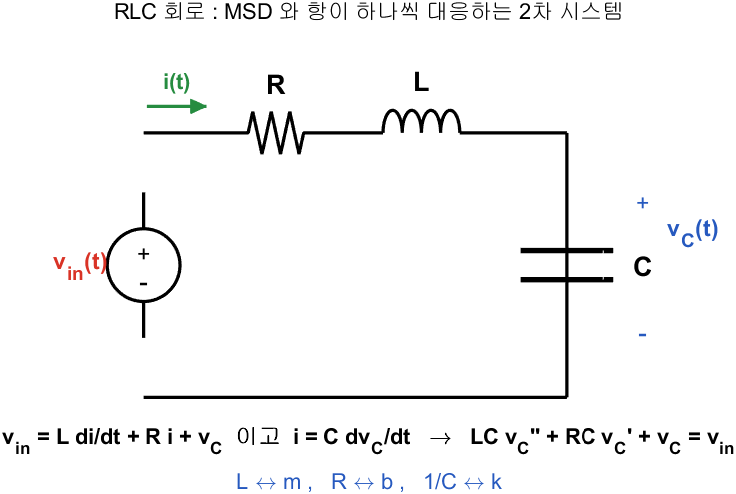

RLC 회로 : 인덕터(관성)와 커패시터(스프링)가 둘 다 있어 2차가 된다

**그림 파일** `rlc_circuit.png` — `common/dg_rc.m` 의 `dg_rc('rlc')` · 다시 만들려면 `make_figures('rlc_circuit')`

**만드는 곳** — `common/dg_rc.m`. 인수 없이 `dg_rc()` 로 부르면 인덕터가 빠진 **1차 RC 회로**가 나옵니다 (같은 절 앞쪽 그림)

그림 해석 — **MSD 와 하나씩 짝을 지어 보십시오**

에너지를 저장하는 것이 $L$ 과 $C$ 로 **둘**이라 2차가 됩니다. MSD 와 완전히 같은 이유입니다.

**이것이 이 과목이 쓸 만한 이유입니다.** 기계든 전기든 유체든, 식이 같으면 **같은 도구로 다룹니다.**

앞에서 본 RC 회로에는 커패시터만 있었습니다. 그래서 1차였습니다. 여기에 인덕터를 더하면 저장하는 곳이 둘이 되어 **2차**가 되고, 그때부터 진동합니다.

- 저장하는 곳이 하나 $\rightarrow$ 1차 $\rightarrow$ 진동 없음

- 저장하는 곳이 둘   $\rightarrow$ 2차 $\rightarrow$ 서로 주고받으며 진동 가능

그네가 흔들리는 것도 같은 이유입니다. 위치에너지와 운동에너지가 서로 주고받습니다.


$$L\,\frac{d^2 q}{dt^2} + R\,\frac{dq}{dt} + \frac{1}{C}\,q = V(t)$$


L_ = 1; R_ = 0.4; Cc_ = 1;
G_rlc = tf(1, [L_ R_ 1/Cc_]);
fprintf('=== RLC 회로 (L = %.1f, R = %.1f, C = %.1f) ===\n', L_, R_, Cc_);

=== RLC 회로 (L = 1.0, R = 0.4, C = 1.0) ===


fprintf('  극점 : %s   <- 복소수. 즉 진동합니다\n\n', mat2str(round(pole(G_rlc).', 3)));

  극점 : [-0.2+0.98i -0.2-0.98i]   <- 복소수. 즉 진동합니다



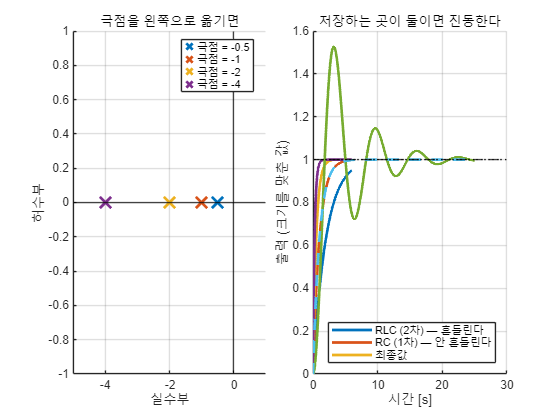

t_rlc = (0:0.02:25)';
plot(t_rlc, step(G_rlc, t_rlc), 'LineWidth', 2); hold on;
plot(t_rlc, step(tf(1,[1 1]), t_rlc), '--', 'LineWidth', 2);
yline(1, 'k:'); grid on;
xlabel('시간 [s]'); ylabel('출력 (크기를 맞춘 값)');
legend('RLC (2차) — 흔들린다', 'RC (1차) — 안 흔들린다', '최종값', 'Location','southeast');
title('저장하는 곳이 둘이면 진동한다');

## 5-2. 같은 절차를 RC 회로에 — 5 분이면 됩니다

생김새가 전혀 다른데 절차가 똑같다는 것을 바로 보여 드리겠습니다.

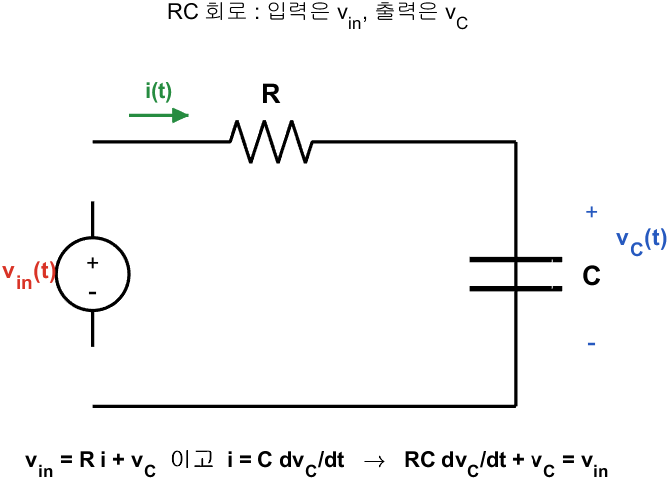

RC 회로

**그림 파일** `rc_circuit.png` — `common/dg_rc.m` 의 `dg_rc` · 다시 만들려면 `make_figures('rc_circuit')`

**만드는 곳** — `common/dg_rc.m` (`make_figures('rc_circuit')`)

그림 해석

외울 규칙 하나 — **에너지를 저장하는 부품의 개수가 시스템의 차수**입니다.

- **1단계** 그림은 위와 같습니다

- **2단계** 키르히호프 전압 법칙 : $v_{in} = R\,i + v_C$, 그리고 커패시터는 $i = C\,\frac{dv_C}{dt}$ 이므로


$$R\,C\,\frac{dv_C}{dt} + v_C = v_{in}$$


- **3단계** 라플라스 변환 (초기조건 $0$)


$$R\,C\,s\,V_C(s) + V_C(s) = V_{in}(s)$$


- **4단계** 출력 나누기 입력


$$G(s) = \frac{V_C(s)}{V_{in}(s)} = \frac{1}{RCs + 1}$$


미분이 한 번뿐이라 **1계** 미분방정식이고, 따라서 **극점이 하나**입니다. $\tau = RC$ 를 시정수라고 부릅니다.

R_ = 1e3; C_ = 100e-6;
G_rc = tf(1, [R_*C_ 1]);
fprintf('=== RC 회로 ===\n');

=== RC 회로 ===


G_rc


G_rc =
 
      1
  ---------
  0.1 s + 1
 
연속시간 전달 함수입니다.
모델 속성


fprintf('  시정수 tau = R*C = %.3f s\n', R_*C_);

  시정수 tau = R*C = 0.100 s


fprintf('  극점 = -1/tau = %.3f\n\n', pole(G_rc));

  극점 = -1/tau = -10.000



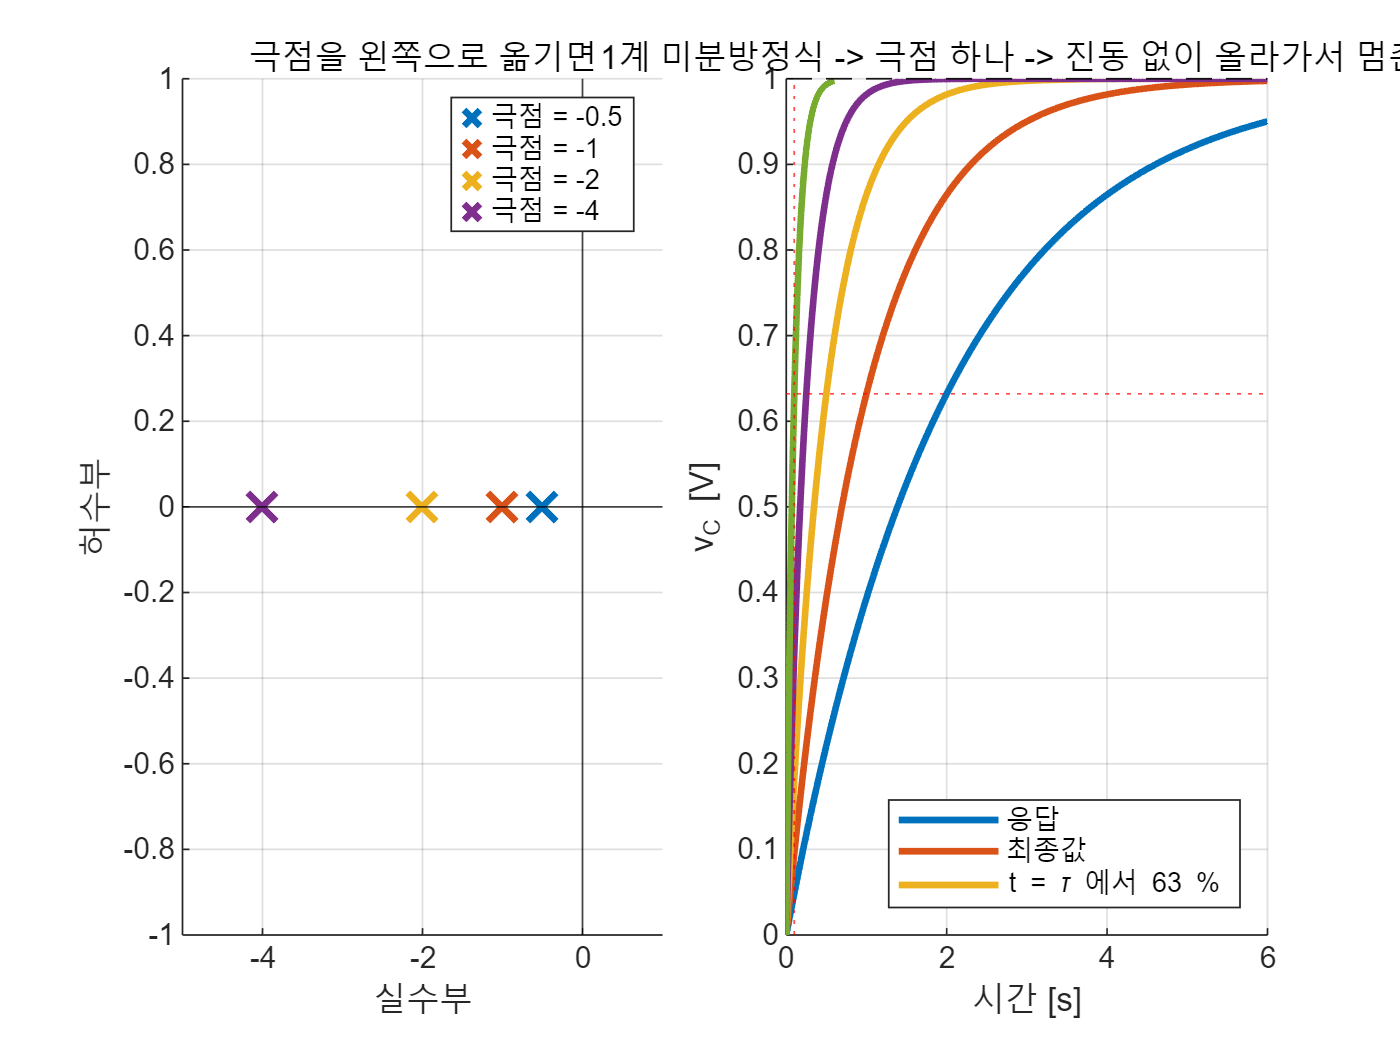

t_rc = (0:0.001:0.6)';
plot(t_rc, step(G_rc, t_rc), 'LineWidth', 2); hold on;
yline(1, 'k--'); yline(0.632, 'r:'); xline(R_*C_, 'r:');
grid on; xlabel('시간 [s]'); ylabel('v_C [V]');
legend('응답', '최종값', 't = \tau 에서 63 %', 'Location','southeast');
title('1계 미분방정식 -> 극점 하나 -> 진동 없이 올라가서 멈춘다');

## 6. 2차 표준형 — $\omega_n$ 과 $\zeta$

제어공학에서는 2차 시스템을 항상 이 형태로 놓고 이야기합니다.


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}=\frac{1}{ms^2 + bs + k$$


우리 식을 $s^2$ 계수가 $1$ 이 되도록 정리하고 분모끼리 비교하면


$$\omega_n = \sqrt{\frac{k}{m}}, \qquad \zeta = \frac{b}{2\sqrt{mk}}$$


물리적으로 읽으면

- $\omega_n$ **고유진동수** — 스프링이 셀수록, 질량이 가벼울수록 빨리 흔들린다

- $\zeta$ **감쇠비** — 댐퍼가 셀수록 진동이 빨리 죽는다

그런데 이 두 숫자가 $s$** 평면의 어디**를 가리키는지 알아야 뒤가 편합니다. 극점을 극좌표로 보면 두 숫자가 그대로 보입니다.

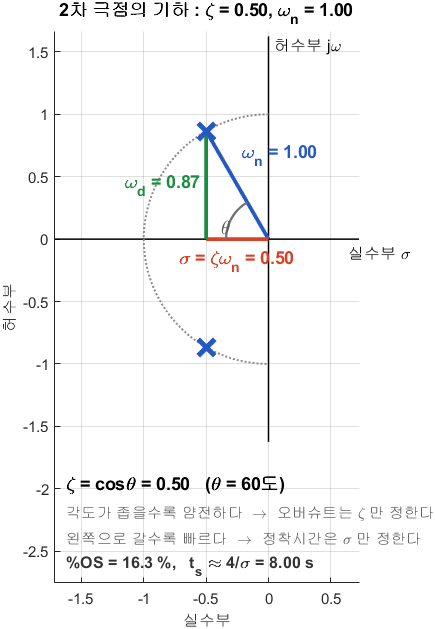

$\omega_n$ 은 거리, $\zeta$ 는 각도의 코사인

**그림 파일** `zeta_geo_05.png` — `common/dg_zeta_geo.m` 의 `dg_zeta_geo` · 다시 만들려면 `make_figures('zeta_geo_05')`

**만드는 곳** — `make_figures.m` 의 `dg_zeta_geo(0.5, 1)` **다른 값으로 보려면** — 명령창에 `dg_zeta_geo(0.3, 2)` 처럼 직접 부르면 됩니다

그림 해석

읽을 것

- $\omega_n$ 은 **원점에서 극점까지의 거리**다

- $\zeta=cos(\theta)$ 는 그 선이 음의 실축과 이루는 각 $\theta$ 의 **코사인**이다

- 실수부 $\sigma = \zeta\omega_n$ 이 **얼마나 빨리 사그라드는가**를 정한다

- 허수부 $\omega_d = \omega_n\sqrt{1-\zeta^2}$ 가 **얼마나 빨리 흔들리는가**를 정한다

감쇠비를 줄이면 각이 벌어지고 오버슈트가 커집니다.

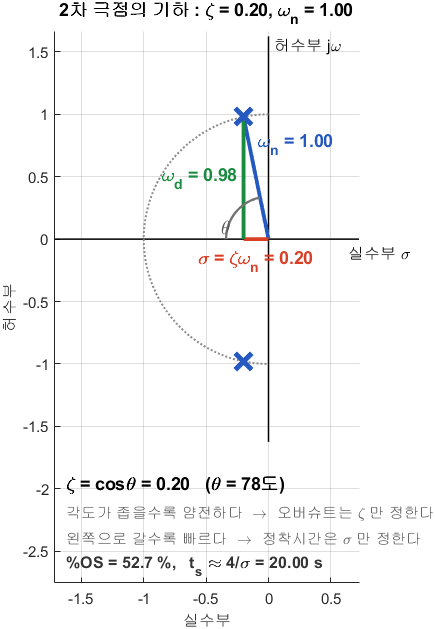

감쇠비를 0.2 로 줄이면 각이 벌어진다

**그림 파일** `zeta_geo_02.png` — `common/dg_zeta_geo.m` 의 `dg_zeta_geo` · 다시 만들려면 `make_figures('zeta_geo_02')`

**만드는 곳** — `common/dg_zeta_geo.m` 을 `dg_zeta_geo(0.2, 1)` 로 부릅니다 **직접 바꿔 보려면** — 명령창에 `dg_zeta_geo(0.9, 1)` 처럼 직접 부르면 됩니다

그림 해석 — **앞 그림(**$\zeta = 0.5$**)과 숫자를 견주어 보십시오**

**극점이 원 위를 미끄러졌을 뿐인데 두 성질이 동시에 나빠졌습니다.** $\zeta$ 를 줄이면 더 튀고 더 오래 걸립니다. 이것이 감쇠비의 뜻입니다.

**4주차의 사양 공식과 6주차의 sgrid 가 전부 이 그림 한 장에서 나옵니다.** 오버슈트는 각도만, 정착시간은 실수부만 본다는 것이 여기서 바로 보입니다.

**왜 굳이 이 두 숫자로 바꿔 쓰는가?**

$m, b, k$ 는 세 개인데 $\omega_n, \zeta$ 는 두 개입니다. 응답의 모양을 결정하는 데는 두 개면 충분하기 때문입니다. 질량이 2배여도 스프링이 2배면 응답 모양은 똑같습니다.

4주차에서 배울 시간응답 사양은 전부 이 두 숫자로 기술됩니다.

damp(G)

                                                                   
          극점                 감쇠             주파수            시정수     
                                       (rad/seconds)    (seconds)  
                                                                   
 -1.00e-01 + 9.95e-01i     1.00e-01       1.00e+00       1.00e+01  
 -1.00e-01 - 9.95e-01i     1.00e-01       1.00e+00       1.00e+01  


## 7. 극점과 영점

전달함수를 $G(s) = \frac{N(s)}{D(s)}$ 로 보면

- **극점** (pole) — 분모를 $0$ 으로 만드는 $s$. $G(s)$ 가 무한대가 되는 지점

- **영점** (zero) — 분자를 $0$ 으로 만드는 $s$. $G(s)$ 가 $0$ 이 되는 지점

분모를 $0$ 으로 놓은 식 $D(s)=0$ 을 **특성방정식**이라 하고 그 근이 극점입니다.

"특성"이라는 이름이 붙은 이유가 있습니다. 시스템이 빠른지 느린지, 진동하는지 아닌지, 안정한지 불안정한지가 **전부 이 방정식의 근에서 결정**되기 때문입니다. 입력이 무엇이든 상관없습니다. 시스템 자체의 성격입니다.

## 8. 왜 극점이 응답을 결정하는가

이유는 의외로 단순합니다. **부분분수 전개**를 해 보면 바로 보입니다.

극점이 $p_1$, $p_2$ 인 시스템의 응답을 라플라스 영역에서 쪼개면


$$Y(s) = \frac{A}{s - p_1} + \frac{B}{s - p_2} + (\text{입력이 만든 항})$$


이 되고, 각 항을 시간 영역으로 되돌리면


$$y(t) = A\,e^{p_1 t} + B\,e^{p_2 t} + \ldots$$


입니다. 즉 **극점 하나가 지수함수 항 하나**를 만듭니다. 이것을 **모드**라고 부릅니다.

그러면 극점 위치를 보고 응답을 읽을 수 있습니다. 극점을 $p = \sigma + j\omega$ 라고 쓰면


$$e^{pt} = e^{\sigma t}\,e^{j\omega t} = e^{\sigma t}\;\times\;(\cos\omega t + j\sin\omega t)$$


앞의 $e^{\sigma t}$ 가 **크기**를 맡고, 뒤의 $\cos$, $\sin$ 이 **흔들림**을 맡습니다.

이므로 두 부분이 각각 다른 일을 합니다.

- **실수부 **$\sigma$ — 크기를 정한다. 음수면 줄어들고 양수면 커진다

- **허수부 **$\omega$ — 흔들리는 빠르기를 정한다

- 실수부가 하나라도 $0$ 보다 크면 그 항이 커지므로 **전체가 발산**한다

말로 하면 어렵습니다. 그림으로 봅니다.

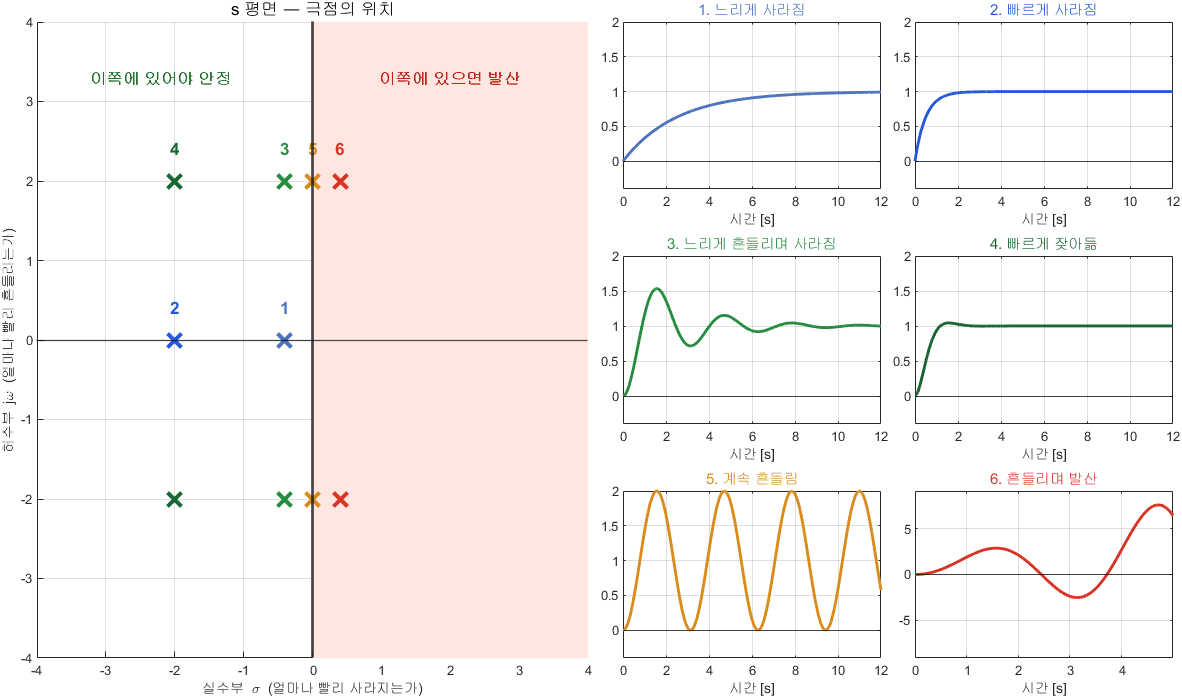

극점 위치와 응답 모양

**그림 파일** `polemap.png` — `common/dg_polemap.m` 의 `dg_polemap` · 다시 만들려면 `make_figures('polemap')`

**만드는 곳** — `common/dg_polemap.m` (`make_figures('polemap')`)

그림 해석 — **왼쪽의 번호와 오른쪽의 번호를 짝지어 보십시오**

이 그림 한 장이 앞으로 열두 주 동안 쓸 지도입니다. **왼쪽으로 갈수록 빠르고, 위아래로 갈수록 흔들리고, 오른쪽은 금지 구역**입니다.

## 7-1. 극점을 옮기면 응답이 어떻게 변하는가

극점의 **실수부와 허수부를 따로** 움직여 보면 각각이 무엇을 정하는지 분명해집니다.

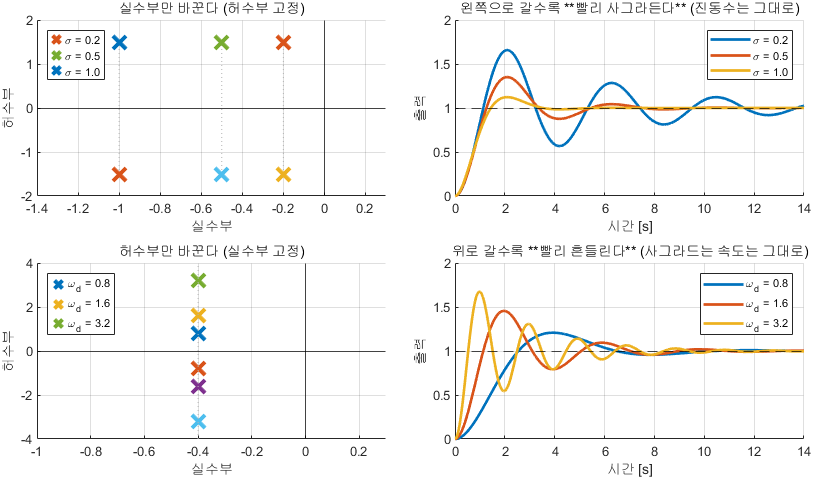

실수부는 사그라드는 속도, 허수부는 흔들리는 속도

**그림 파일** `w02_pole_time.png` — `make_figures.m` 의 `fig_w02_pole_to_time` · 다시 만들려면 `make_figures('w02_pole_time')`

**만드는 곳** — `make_figures.m` 의 `fig_w02_pole_to_time`

그림 해석

위 두 칸 — 허수부를 고정하고 실수부만 왼쪽으로 옮기면 **진동 주기는 그대로인데 봉투가 빨리 줄어듭니다.**

아래 두 칸 — 실수부를 고정하고 허수부만 올리면 **사그라드는 속도는 그대로인데 더 촘촘히 흔들립니다.**

이것이 2차 응답을 읽는 전부입니다.


$$y(t) \propto e^{-\sigma t}\cos(\omega_d t + \phi) \qquad \sigma = \text{실수부}, \quad \omega_d = \text{허수부}$$


## 8-0. 같은 것을 나란히 다시

위 그림을 좌우로 짝지어 보면 이렇게 됩니다. 왼쪽 열이 극점 위치, 오른쪽 열이 그 결과인 응답입니다.

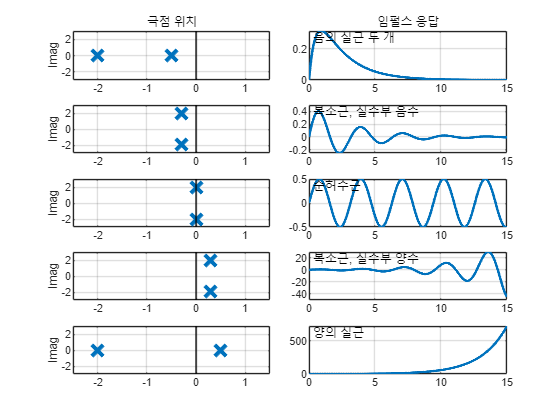

cases = { '음의 실근 두 개',   1/((s+0.5)*(s+2))
          '복소근, 실수부 음수', 1/(s^2+0.6*s+4)
          '순허수근',           1/(s^2+4)
          '복소근, 실수부 양수', 1/(s^2-0.6*s+4)
          '양의 실근',          1/((s-0.5)*(s+2)) };
t2 = 0:0.01:15;
tiledlayout(5,2,'TileSpacing','compact')
for i = 1:5
    nexttile
    pl = pole(cases{i,2});
    plot(real(pl), imag(pl), 'x', 'MarkerSize',12, 'LineWidth',3); hold on
    xline(0,'k-','LineWidth',1.5); grid on
    xlim([-2.5 1.5]); ylim([-3 3]); ylabel('Imag')
    if i==1, title('극점 위치'); end
    nexttile
    plot(t2, impulse(cases{i,2}, t2), 'LineWidth',2); grid on
    if i==1, title('임펄스 응답'); end
    text(0.02,0.85, cases{i,1}, 'Units','normalized','FontSize',9)
end

## 8-1. 한 문장으로 요약하면

**허수축을 기준으로 극점이 왼쪽에 있으면 안정, 오른쪽에 하나라도 있으면 불안정입니다.**

이 한 문장이

- 5주차 안정도 판별의 전부이고

- 6주차 근궤적이 "이득을 바꾸면 극점이 어디로 움직이는가"를 그리는 이유이며

- 13주차 극배치가 "극점을 원하는 곳에 놓겠다"고 하는 이유입니다

오늘 이것만 확실히 잡고 가면 됩니다.

## 9. 댐퍼를 세게 하면 극점은 어디로 가는가

극점은 특성방정식 $ms^2+bs+k=0$ 의 근이므로 근의 공식을 쓰면


$$s = \frac{-b \pm \sqrt{b^2-4mk}}{2m}$$


판별식의 부호에 따라 세 가지로 갈립니다.

- $b^2 < 4mk$ 즉 $\zeta<1$ — 복소근 → **부족감쇠**, 진동하며 수렴

- $b^2 = 4mk$ 즉 $\zeta=1$ — 중근 → **임계감쇠**, 진동 없이 가장 빠르게

- $b^2 > 4mk$ 즉 $\zeta>1$ — 서로 다른 실근 → **과감쇠**, 진동 없지만 느리게

$b$ 를 $0$ 부터 키우면서 극점이 그리는 자취를 따라가 봅니다. 두 극점은 허수축에서 출발해 반지름 $\omega_n$ 인 원을 따라 왼쪽으로 이동하다가, $s = -\omega_n$ 에서 만난 뒤 실축을 따라 좌우로 갈라집니다.

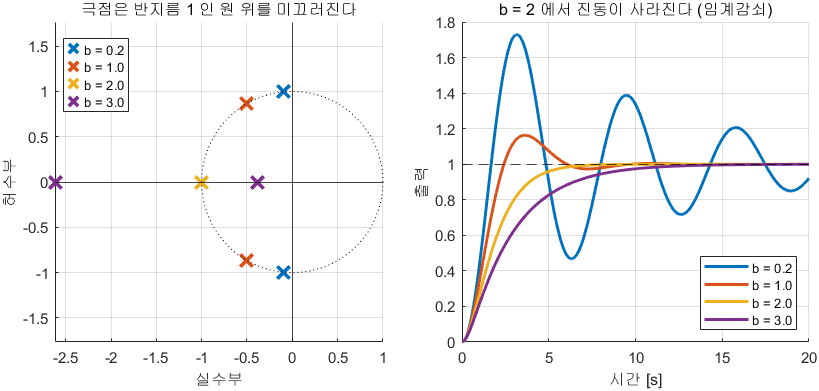

댐퍼를 키우면 극점이 실축으로 모인다

**그림 파일** `w02_damper_sweep.png` — `make_figures.m` 의 `fig_damper_sweep` · 다시 만들려면 `make_figures('w02_damper_sweep')`

**만드는 곳** — `make_figures.m` 의 `fig_damper_sweep` **직접 바꿔 보려면** — `W02_02_msd_derivation.m` 의 **3절**에서 `b` 목록을 바꿔 실행

그림 해석 — **왼쪽 **$\times$** 와 오른쪽 곡선을 색으로 짝지으십시오**

**댐퍼를 키운다고 계속 좋아지지 않습니다.** $b = 2$ 가 최고이고 그보다 키우면 오히려 느려집니다. 4주차에서 이것을 $\zeta = 1$ 로 다시 만납니다.

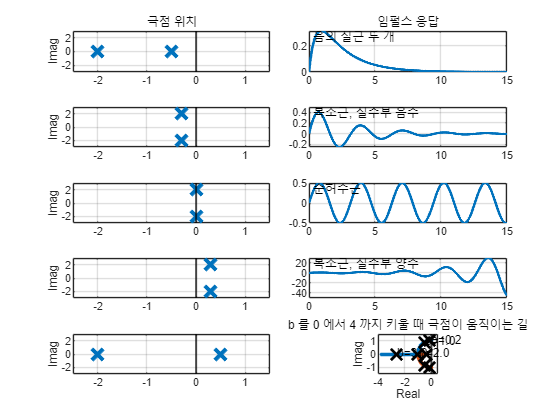

b_sweep = linspace(0,4,400);
pp = zeros(2,numel(b_sweep));
for i=1:numel(b_sweep), pp(:,i) = roots([m b_sweep(i) k]); end
plot(real(pp(1,:)), imag(pp(1,:)), '.', 'MarkerSize',8); hold on
plot(real(pp(2,:)), imag(pp(2,:)), '.', 'MarkerSize',8)
for bm = [0.2 1.0 2.0 3.0]
    pm = roots([m bm k]);
    plot(real(pm), imag(pm), 'kx', 'MarkerSize',12, 'LineWidth',2)
    text(real(pm(1))+0.05, imag(pm(1))+0.08, sprintf('b=%.1f',bm), 'FontSize',9)
end
xline(0,'k-','LineWidth',1.5); grid on; axis equal
xlim([-4 0.5]); ylim([-1.5 1.5]); xlabel('Real'); ylabel('Imag')
title('b 를 0 에서 4 까지 키울 때 극점이 움직이는 길')

## 9-1. 방금 우리가 한 것이 근궤적입니다

파라미터 하나를 바꾸면서 극점이 어디로 움직이는지 그린 이 그림이 바로 6주차에 배울 **근궤적**(root locus)입니다.

- 6주차에서는 $b$ 대신 제어이득 $K$ 를 바꾼다

- 그것 말고는 완전히 같다

- 제어기 설계란 결국 **극점이 원하는 자리에 오도록 **$K$** 를 고르는 일**이 된다

오늘 이 그림에 익숙해져 두면 6주차가 훨씬 쉬워집니다.

## 10. 감쇠 상태별 응답

위 그림의 대표 지점들이 실제로 어떤 응답을 만드는지 봅니다.

눈여겨볼 점은 **임계감쇠 **$\zeta=1$** 이 "진동 없이 가장 빠른" 지점**이라는 것입니다. 감쇠를 더 키우면 진동은 여전히 없지만 오히려 느려집니다. 극점 하나가 원점 쪽으로 되돌아오면서 그 느린 극점이 응답을 지배하기 때문입니다.

극점 위치와 응답을 **나란히** 놓고 보면 대응이 한눈에 들어옵니다.

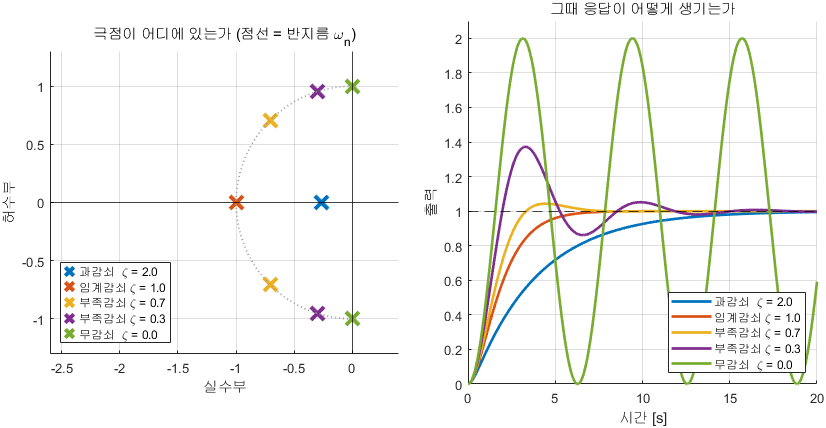

극점이 어디 있는지와 응답이 어떻게 생겼는지

**그림 파일** `w02_damping.png` — `make_figures.m` 의 `fig_w02_damping` · 다시 만들려면 `make_figures('w02_damping')`

**만드는 곳** — `make_figures.m` 의 `fig_w02_damping` **직접 바꿔 보려면** — 이 절 아래 코드에서 `bi` 목록에 값을 더해 실행

그림 해석

왼쪽 그림에서 점선 원의 반지름이 $\omega_n$ 입니다. **다섯 경우가 모두 같은 원 위에** 있습니다. $\zeta$ 만 다르므로 각도만 다릅니다.

- $\zeta = 0$ — 극점이 허수축 위. 영원히 흔들린다

- $\zeta = 0.3$ — 각이 넓다. 많이 넘어간다

- $\zeta = 0.707$ — 각이 $45^\circ$. 오버슈트 약 $4.3\%$

- $\zeta = 1$ — 두 극점이 실축에서 만난다. 진동이 없는 가장 빠른 지점

- $\zeta = 2$ — 실극점 둘로 갈라진다. 느린 쪽이 응답을 지배해 오히려 느려진다

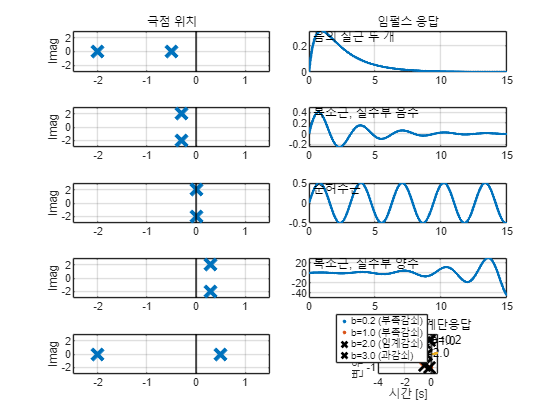

t3 = 0:0.01:30;
for bi = [0.2 1.0 2.0 3.0]
    plot(t3, step(1/(m*s^2+bi*s+k), t3), 'LineWidth',2); hold on
end
yline(1/k,'k--','LineWidth',1.5); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]'); title('댐퍼 값에 따른 계단응답')
legend('b=0.2 (부족감쇠)','b=1.0 (부족감쇠)', ...
       'b=2.0 (임계감쇠)','b=3.0 (과감쇠)','Location','southeast')

## 11. 영점은 무슨 일을 하는가

간단히 말하면 이렇습니다.

- **극점**은 응답의 재료를 정한다

- **영점**은 그 재료를 얼마씩 섞을지를 정한다

그래서 극점을 그대로 두고 영점만 바꾸면, 진동 주파수와 감쇠 속도는 똑같은데 초반 모양만 달라집니다.

아래 그림에서 **오른쪽 영점** $s=+2$ 인 경우를 특히 눈여겨보십시오. 응답이 처음에 **반대 방향으로 갔다가** 돌아옵니다.

이건 실제로 있는 현상입니다. 비행기 고도를 올리려고 조종간을 당기면 순간적으로 고도가 살짝 내려갔다가 올라갑니다. 꼬리날개가 먼저 아래로 눌리기 때문입니다.

이런 시스템은 제어하기 까다롭습니다. 올라가라고 했는데 내려가니 제어기가 "더 세게 당겨야 하나?" 하고 혼동하기 때문입니다.

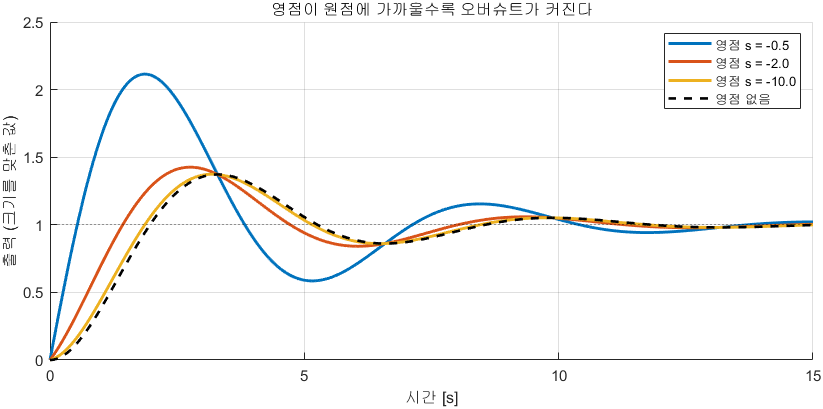

영점이 원점에 가까울수록 오버슈트가 커진다

**그림 파일** `w02_zero_effect.png` — `make_figures.m` 의 `fig_zero_effect` · 다시 만들려면 `make_figures('w02_zero_effect')`

**만드는 곳** — `make_figures.m` 의 `fig_zero_effect` **직접 바꿔 보려면** — 영점을 $+2$ 처럼 **우반면**에 두어 보십시오. 응답이 처음에 반대로 가는 것을 볼 수 있습니다 (역응답)

그림 해석

왜 그런가 — $(s+z)G(s)$ 를 풀어 쓰면 $sG(s) + zG(s)$ 입니다. 앞항이 **미분**입니다. $z$ 가 작을수록 미분 성분의 비중이 커져 초반이 가팔라집니다.

4주차의 오버슈트 공식은 **영점이 없다**고 가정한 것입니다. 그래서 영점이 가까이 있으면 공식이 어긋납니다. 7주차에서 이 문제를 다시 만납니다.

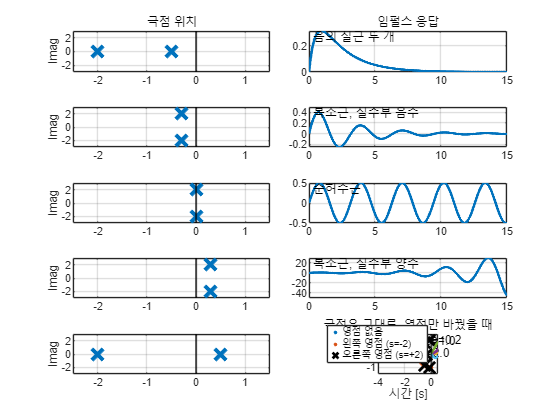

Gb = 4/(s^2+2*s+4);
t4 = 0:0.01:8;
plot(t4, step(Gb,t4), 'LineWidth',2); hold on
plot(t4, step(Gb*(s/2+1),t4), 'LineWidth',2)
plot(t4, step(Gb*(-s/2+1),t4), 'LineWidth',2)
yline(1,'k--'); grid on
xlabel('시간 [s]'); ylabel('y(t)'); title('극점은 그대로, 영점만 바꿨을 때')
legend('영점 없음','왼쪽 영점 (s=-2)','오른쪽 영점 (s=+2)','Location','southeast')

## 12. 전달함수의 한계

질문 하나를 던져 봅니다.

**"물체를 **$0.5\,\mathrm{m}$** 당겨 놓고 힘을 전혀 주지 않은 채 놓았다. 어떻게 되는가?"**

전달함수로 답해 보면 입력 $F=0$ 이므로 $X(s) = G(s)\cdot 0 = 0$ 입니다. 즉 **"아무 일도 안 일어난다"** 고 답합니다. 명백히 틀렸습니다.

이유는 3단계에서 초기조건을 $0$ 으로 두고 버렸기 때문입니다. 전달함수는 입력과 출력의 관계만 담을 뿐, **시스템 내부가 지금 어떤 상태인지는 담지 못합니다.**

못 담는 것이 초기조건만은 아닙니다. 한 장으로 정리하면 이렇습니다.

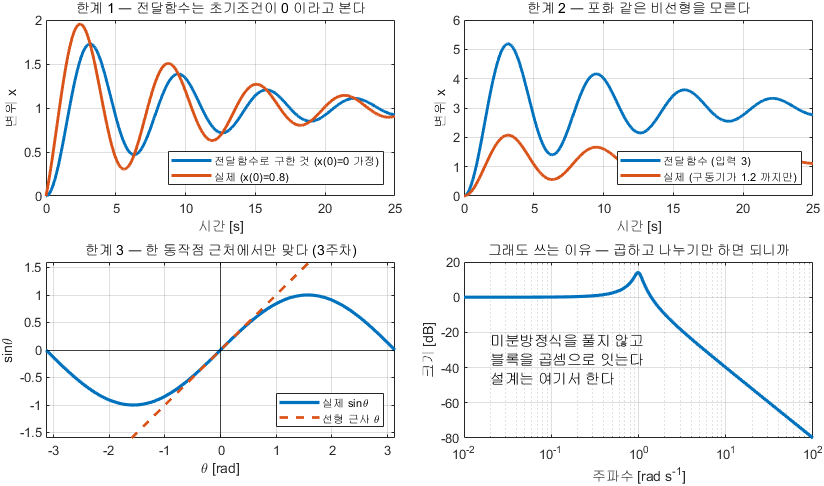

전달함수가 못 다루는 것 세 가지

**그림 파일** `w02_tf_limits.png` — `make_figures.m` 의 `fig_w02_tf_limits` · 다시 만들려면 `make_figures('w02_tf_limits')`

**만드는 곳** — `make_figures.m` 의 `fig_w02_tf_limits`

그림 해석

그런데도 학기 내내 전달함수를 쓰는 이유는 오른쪽 아래 칸에 있습니다. **미분방정식을 풀지 않고 블록을 곱셈으로 이어 붙일 수 있기 때문**입니다. 설계는 거기서 합니다. 그리고 **검증은 반드시 Simulink 로** 합니다.

이 한계를 넘으려면 **세 번째 표현**이 필요합니다. 다음 절에서 소개합니다.

## 12-1. 세 번째 표현 — 상태공간

오늘의 네 단계는 여기서 끝나지 않습니다. **한 칸이 더 있습니다.**


$$\text{미분방정식} \rightarrow \text{라플라스} \rightarrow \text{전달함수} \rightarrow \text{상태공간}$$


앞 절에서 본 한계의 원인은 하나였습니다 — **라플라스 변환할 때 초기조건을 **$0$** 으로 두고 버렸다**는 것입니다.

그러면 **버리지 않는 길**로 가면 됩니다. 라플라스 변환을 아예 하지 않고, 미분방정식을 그대로 두는 것입니다.

**아이디어 — 2계 미분방정식 하나를 1계 두 개로 쪼갠다**

컴퓨터는 1계 미분방정식만 풀 줄 압니다. 그래서 2계짜리를 1계 두 개로 나눕니다. 나누려면 **무엇을 계속 기억하고 있어야 하는지**를 정해야 합니다.

질량-스프링-댐퍼에서 다음 순간을 계산하려면 무엇을 알아야 하는가?

- **위치만?** 부족합니다. 같은 자리라도 날아가는 중인지 멈춰 있는지 다릅니다

- **위치와 속도?** 충분합니다. 이 둘과 앞으로 들어올 힘만 알면 미래가 정해집니다

그래서 이 둘을 **상태**(state)라고 부르고 이름을 붙입니다.


$$x_1 = x \;(\text{위치}), \qquad x_2 = \dot{x} \;(\text{속도})$$


이제 각 상태의 미분을 **상태와 입력만으로** 적습니다.


$$\dot{x}_1 = \dot{x} = x_2$$



$$\dot{x}_2 = \ddot{x} = \frac{1}{m}\left(F - b\dot{x} - kx\right) = -\frac{k}{m}x_1 - \frac{b}{m}x_2 + \frac{1}{m}F$$


둘째 줄은 오늘 2절에서 세운 운동방정식을 $\ddot{x}$ 에 대해 푼 것뿐입니다. **새로운 물리는 하나도 없습니다.** 같은 식을 다르게 적었을 뿐입니다.

## 12-2. 행렬로 묶으면 두 줄이 됩니다

위 두 식의 계수만 뽑아 행렬로 적습니다.


$$\left[\begin{array}{c}\dot{x}_1\\ \dot{x}_2\end{array}\right] = \left[\begin{array}{cc} 0 & 1\\ -\frac{k}{m} & -\frac{b}{m}\end{array}\right] \left[\begin{array}{c}x_1\\ x_2\end{array}\right] + \left[\begin{array}{c}0\\ \frac{1}{m}\end{array}\right] F$$


우리가 재는 것이 위치라면


$$x = \left[\begin{array}{cc}1 & 0\end{array}\right] \left[\begin{array}{c}x_1\\ x_2\end{array}\right] + 0\cdot F$$


이 두 줄을 기호로 쓴 것이 **상태공간 표현**입니다.


$$\dot{x} = Ax + Bu, \qquad y = Cx + Du$$


네 행렬의 뜻만 지금 알아 두면 됩니다.

**왜 이것이 초기조건 문제를 푸는가** — 상태 $x_1, x_2$ 가 식 안에 그대로 살아 있습니다. 시작할 때 $x_1(0) = 0.5$ 라고 넣어 주면 됩니다. 전달함수에는 그 값을 넣을 자리가 아예 없었습니다.

**오늘은 여기까지입니다.** 상태를 고르는 요령, 표현이 여러 개인 이유, 상태공간으로만 할 수 있는 일은 **3주차 4~6절**에서 제대로 다룹니다. 오늘은 "세 번째 표현이 있고, 그것이 초기조건을 담는다" 만 알면 됩니다.

## 12-3. `ss` — 오늘의 마지막 새 명령

- **하는 일** — 네 행렬 $A, B, C, D$ 로 상태공간 모델을 만든다

- **입력** — `ss(A, B, C, D)`. 행렬 네 개

- **출력** — 상태공간 객체. `tf` 로 만든 것과 거의 똑같이 쓸 수 있다

함께 알아 둘 것

- `tf(sys)` — 상태공간을 전달함수로 바꾼다

- `ss(G)` — 전달함수를 상태공간으로 바꾼다

- `initial(sys, x0, t)` — **초기조건에서 출발한 응답**. `tf` 에는 없는 기능

주의

- $A$ 는 정사각행렬이어야 하고, $B$ 의 행 수가 $A$ 와 같아야 한다

- $C$ 의 열 수도 $A$ 와 같아야 한다. 크기가 안 맞으면 바로 오류가 난다

- `initial` 의 $x_0$ 는 **열벡터**로 준다

이제 손으로 만든 행렬이 정말 같은 시스템인지 확인해 봅니다.

A_hand = [0 1; -k/m, -b/m];
B_hand = [0; 1/m];
C_hand = [1 0];
D_hand = 0;
sys_ss = ss(A_hand, B_hand, C_hand, D_hand);

fprintf('=== 손으로 만든 상태공간 ===\n');

=== 손으로 만든 상태공간 ===


fprintf('  m = %.1f, b = %.1f, k = %.1f\n', m, b, k);

  m = 1.0, b = 0.2, k = 1.0


disp('A ='); disp(A_hand);

A =
         0    1.0000
   -1.0000   -0.2000



disp('B ='); disp(B_hand);

B =
     0
     1



fprintf('C = %s ,  D = %g\n\n', mat2str(C_hand), D_hand);

C = [1 0] ,  D = 0




fprintf('=== 전달함수로 되돌리면 ===\n');

=== 전달함수로 되돌리면 ===


tf(sys_ss)


ans =
 
         1
  ---------------
  s^2 + 0.2 s + 1
 
연속시간 전달 함수입니다.


fprintf('  오늘 4단계에서 구한 G(s) 의 극점 : %s\n', ...
        mat2str(round(sort(pole(G)).', 4)));

  오늘 4단계에서 구한 G(s) 의 극점 : [-0.1-0.995i -0.1+0.995i]


fprintf('  상태공간에서 되돌린 것의 극점    : %s\n', ...
        mat2str(round(sort(pole(tf(sys_ss))).', 4)));

  상태공간에서 되돌린 것의 극점    : [-0.1-0.995i -0.1+0.995i]


fprintf('  --> 같은 시스템입니다. 표현만 다릅니다.\n');

  --> 같은 시스템입니다. 표현만 다릅니다.


## 12-4. 이제 아까 그 질문에 답할 수 있습니다

**"물체를 **$0.5\,\mathrm{m}$** 당겨 놓고 힘 없이 놓았다. 어떻게 되는가?"**

상태공간에는 초기조건을 넣을 자리가 있으므로 `initial` 로 바로 답합니다. 물리적으로 기대하는 답은 **진동하며 제자리로 돌아온다** 입니다.

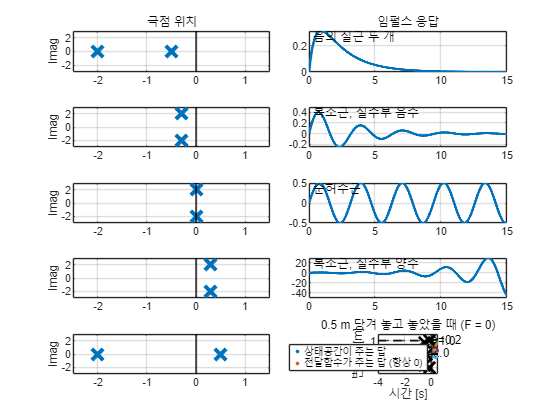

t5 = 0:0.01:40;
plot(t5, initial(sys_ss, [0.5;0], t5), 'LineWidth',2); hold on
plot(t5, zeros(size(t5)), 'k--', 'LineWidth',2)
yline(0,'k:'); grid on
xlabel('시간 [s]'); ylabel('변위 x [m]')
title('0.5 m 당겨 놓고 놓았을 때 (F = 0)')
legend('상태공간이 주는 답','전달함수가 주는 답 (항상 0)','Location','northeast')

파란 곡선이 우리가 기대한 답입니다. 검은 점선이 전달함수의 답이고요.

**이것으로 오늘의 사슬이 완성되었습니다.**

다음 절에서 이 셋을 Simulink 에 나란히 놓고 **정말 같은지** 확인합니다.

## 13. Simulink 로 확인하기 — 세 표현을 나란히

모델 `W02_MSD_ThreeWays.slx` 에는 **오늘 배운 세 표현이 그대로 하나씩** 들어 있습니다. 위에서 아래로 세 갈래입니다.

셋을 같은 입력으로 동시에 구동하고 Scope 한 화면에 겹쳐 봅니다.

## 13-1. 처음 보는 블록 세 가지

모델을 열기 전에 블록 이름을 짚고 갑니다. **처음 보는 것이 셋 있습니다.**

`Integrator` 를 두 개 쓰는 이유

- 운동방정식을 $\ddot{x} = (F - b\dot{x} - kx)/m$ 로 정리한다

- 왼쪽 끝에서 $\ddot{x}$ 를 만들고 적분하면 $\dot{x}$

- 한 번 더 적분하면 $x$

- 그 $x$ 와 $\dot{x}$ 를 다시 앞으로 되먹여 $kx$ 와 $b\dot{x}$ 를 만든다

**즉 블록선도가 곧 미분방정식입니다.** 되먹임 선 두 개가 스프링과 댐퍼입니다.

`Integrator` 와 `Transfer Fcn` 의 결정적 차이

- `Integrator` 를 더블클릭하면 `Initial condition` 칸이 **있다**

- `Transfer Fcn` 을 더블클릭하면 그 칸이 **없다**

- `State-Space` 에는 `Initial conditions` 칸이 **있다**

12절에서 말로 설명한 한계가 **블록 다이얼로그에 그대로 있습니다.** 모델을 열면 직접 확인해 보십시오.

## 13-2. 두 가지 실험

`W02_03_run_simulink.m` 이 실험을 두 번 합니다.

**실험 1 — 초기조건 **$0$**, 계단 입력**

세 응답이 **완전히 겹칩니다** (차이가 $10^{-6}$ 수준). 계산 방식은 전혀 다른데 답이 같은 이유는 셋 다 결국 같은 미분방정식이기 때문입니다.

**실험 2 — 초기조건 **$0.5\,\mathrm{m}$

**경로 B 만 반응하지 못합니다.** 넣을 칸이 없으니 당연합니다. A 와 C 는 진동하며 제자리로 돌아옵니다.

이 두 실험이 오늘 배운 것을 한 번에 확인해 줍니다 — **세 표현은 같은 것이지만, 담는 정보는 다르다.**

모델은 모델을 열고 `Ctrl+T` 를 눌러도 실행됩니다. Scope 가 자동으로 열립니다.

## 13-3. 오늘 나온 명령을 여러 가지로 써 본다

같은 시스템을 세 가지 표현으로 오갈 수 있다는 것이 오늘의 요지였습니다. 그 왕복을 명령으로 어떻게 하는지 한자리에 모았습니다.

두 번째 칸의 `'v'` 는 "벡터로 달라" 는 뜻입니다. 빼면 셀 배열로 나와 다루기 번거롭습니다.

s = tf('s');

% (1) 같은 시스템을 세 방식으로 만들고 대조한다
Ga = tf(4, [1 0.8 4]);
Gb = zpk([], roots([1 0.8 4]).', 4);
Gc = 4/(s^2 + 0.8*s + 4);
fprintf('tf 대 s 연산자 : %.2e,   tf 대 zpk : %.2e\n', ...
        norm(Ga-Gc, inf), norm(tf(Gb)-Gc, inf));

tf 대 s 연산자 : 0.00e+00,   tf 대 zpk : 1.49e-15



% (2) 값을 꺼내는 세 가지 명령
[zz, pp_, kk] = zpkdata(Gc, 'v');
[nn, dd]      = tfdata(Gc, 'v');
fprintf('zpkdata : 영점 %s, 극점 %s, 이득 %.4g\n', ...
        mat2str(round(zz.',3)), mat2str(round(pp_.',3)), kk);

zpkdata : 영점 zeros(1,0), 극점 [-0.4+1.96i -0.4-1.96i], 이득 4


fprintf('tfdata  : 분자 %s, 분모 %s\n', mat2str(nn), mat2str(dd));

tfdata  : 분자 [0 0 4], 분모 [1 0.8 4]



% (3) 극영점 상쇄가 있으면 minreal 이 정리해 준다
Gcancel = (s+2)/((s+1)*(s+2));
fprintf('상쇄 전 극점 %s -> minreal 뒤 %s\n', ...
        mat2str(round(pole(Gcancel).',3)), ...
        mat2str(round(pole(minreal(Gcancel, 1e-6)).',3)));

상쇄 전 극점 [-2 -1] -> minreal 뒤 -1



% (4) 임펄스응답은 계단응답의 미분이다
tt = (0:0.001:15)';
ys = step(Gc, tt);  yi = impulse(Gc, tt);
fprintf('impulse 와 계단응답의 수치미분 차이 : %.3e (미분 오차)\n', ...
        max(abs(yi(2:end) - diff(ys)/0.001)));

impulse 와 계단응답의 수치미분 차이 : 1.999e-03 (미분 오차)



% (5) 전달함수로는 못 하고 상태공간으로만 되는 일
Gss = ss([0 1; -4 -0.8], [0; 4], [1 0], 0);   % 물리 상태 : 위치와 속도
y_ini = initial(Gss, [0.5; 0], tt);
fprintf('초기 위치 0.5 에서 놓았을 때 : 시작 %.3f -> 끝 %.4f\n', ...
        y_ini(1), y_ini(end));

초기 위치 0.5 에서 놓았을 때 : 시작 0.500 -> 끝 -0.0008


## 14. 오늘의 정리

- 모델링은 **물리법칙 → 미분방정식 → 라플라스 변환 → 전달함수** 네 단계다. 어떤 시스템이든 절차는 같고 바뀌는 것은 1단계의 물리 법칙뿐이다

- 2차 시스템은 $\omega_n$ 과 $\zeta$ 두 숫자로 요약된다

- 극점은 특성방정식의 근이고, 응답에 나타나는 모드 $e^{pt}$ 의 지수다

- 극점이 전부 좌반면에 있으면 안정, 우반면에 하나라도 있으면 불안정

- 영점은 모드가 섞이는 비율을 바꾼다. 오른쪽 영점은 응답을 잠깐 반대로 보낸다

- **전달함수는 초기조건을 담지 못한다.** 그 한계를 넘는 것이 상태공간이다

- 상태공간은 2계 미분방정식을 **1계 두 개로 쪼갠 것**이다. $\dot{x}=Ax+Bu$, $y=Cx+Du$ 두 줄이고, 상태가 식 안에 살아 있어 초기조건을 그대로 넣을 수 있다

- **같은 시스템의 세 표현** — 미분방정식 · 전달함수 · 상태공간. Simulink 의 세 경로가 그것을 눈으로 확인해 준다

## 다음 주 예고

3주차에서는 두 가지를 합니다.

- **블록선도** — 시스템 여러 개가 직렬 · 병렬 · 되먹임으로 얽혀 있을 때 전체 전달함수를 구하는 규칙

- **선형화** — 이번 학기 전반부에서 가장 중요한 개념

세상의 거의 모든 시스템은 사실 **비선형**입니다. 우리가 지금까지 쓴 선형 이론을 어떻게 적용할 수 있는가? 그 답이 선형화입니다.

진자를 예로 들어, 같은 시스템인데도 어느 지점 근처에서 선형화하느냐에 따라 안정한 모델이 나오기도 하고 불안정한 모델이 나오기도 하는 것을 직접 확인합니다.